### **SISO Communication System using QPSK Modulation **

In QPSK, each symbol is represented by 2 bits: the first bit (or odd bits) corresponds to the real part, and the second bit (or even bits) corresponds to the imaginary part of the symbol in 'symvec'. Each symbol energy Es is normalized to 1, and the Gray-coded symbols are as follows:

11→ $\frac{1}{\sqrt{2}}+i\frac{1}{\sqrt{2}}$

01→ $-\frac{1}{\sqrt{2}}+i\frac{1}{\sqrt{2}}$

11→ $-\frac{1}{\sqrt{2}}-i\frac{1}{\sqrt{2}}$

10→ $\frac{1}{\sqrt{2}}-i\frac{1}{\sqrt{2}}$

Gray mapping is used to minimize bit error rate by ensuring only one bit change between adjacent symbols.

Since each symbol is represented by 2 bits in QPSK modulation, the relationshop between symbol energy $E_s$ and bit energy $E_b$ is given by $E_s =kE_b$, where $k$ is the number of bits per symbol. For QPSK, k can be derived from $\log_2 M$, where M=4 is the number of distinct symbols. This gives the relation $E_s =2E_b$.

When converting from $\frac{E_s }{N_0 }\left(\mathrm{dB}\right)$ to $\frac{E_b }{N_0 }\left(\mathrm{dB}\right)$, we use the formula:


$$\frac{E_s }{N_0 }\left(\mathrm{dB}\right)=\frac{E_b }{N_0 }\left(\mathrm{dB}\right)+10\log_{10} \left(k\right)$$


For QPSK, k=2. $10\log_{10} \left(2\right)\approx 3\left(\mathrm{dB}\right)$

Thus,


$$\frac{E_b }{N_0 }\left(\mathrm{dB}\right)=\frac{E_s }{N_0 }\left(\mathrm{dB}\right)-3\left(\mathrm{dB}\right)$$


### **Simulation Setup**

M=4;              % QPSK
m=2;              % represent each symbol with 2 bits
Es=1;             % symbol energy
Nbits = 1e6;      % number of bits
Rs = 1;           % symbol rate
Fs = 4;           % sampling rate
sps = Fs/Rs;      % samples per symbol
EsN0dB = -3:1:20;
EbN0dB = EsN0dB-3; 
N0 = 10.^(-EsN0dB/10);
hrrc = rrc2((-6:1/sps:6)',0.2,1); % Generate square-root raised cosine(rrc) pulse shaping filter 

% Tx
bitvec = randi([0,1],[Nbits,1]); % Generate random bits
symvec = complex(2*bitvec(1:2:end)-1,2*bitvec(2:2:end)-1)/sqrt(2);

#### AWGN Channel

Now, we are passing our QPSK-modulated waveform through a root-raised-cosine (RRC) pulse shaping filter and then through an additive white Gaussian noise (AWGN) channel. We are sampling the signal over a range of SNR values from -3 dB to 20 dB. Our goal is to compare the bit error rate (BER) obtained from demodulation with the theoretical BER for Gray-mapped QPSK. The BER for QPSK is given by the following expression: 


$$\begin{array}{l}
\rho =Q\left(\sqrt{\frac{E_s }{N_0 }}\right)\\
{\mathrm{BER}}_{\mathrm{QPSK}} =\rho \cdot \left(1-\frac{1}{2}\rho \right)
\end{array}$$


The transmitted signal 'txvec' is obtained by upsampling the QPSK complex symbol vector 'symvec' and then convolving it with the RRC filter 'hrrc'.

The variable 'sig2' represents the noise power, $\sigma^2$. This value changes with SNR because $N_0$� (the noise power spectral density) is dependent on SNR. In the equation, $\frac{N_0 }{2}$ is used instead of $N_0$� since the noise power is equally distributed between the real and imaginary components of the signal for QPSK modulation.

The line "noisevec = sqrt(sig2)*complex(randn(size(txvec)),randn(size(txvec)))" generates complex noise with a standard normal distribution (mean=0, standard deviation=1). The noise is then scaled by 'sqrt(sig2)' to adjust for different SNR levels, ensuring that the noise power corresponds to the desired SNR. 

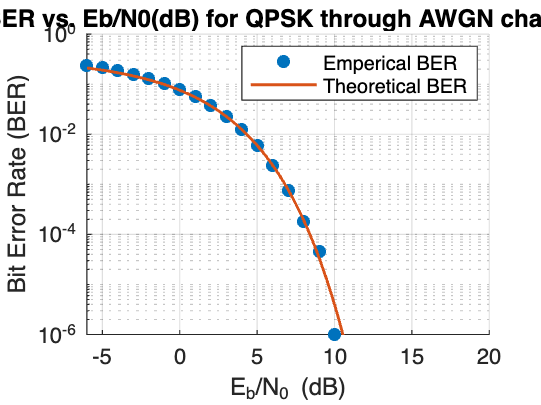

txvec = conv(upsample(symvec,sps),hrrc,'same');

BER=zeros(1,length(EsN0dB));
for i=1:length(EsN0dB)
    
    sig2 = (N0(i)/2)*Fs;
    noisevec = sqrt(sig2)*complex(randn(size(txvec)),randn(size(txvec)));
    % Rx
    rxvec = txvec + noisevec; % length=(2e6x1)
    
    % Pass the received signal rxvec through a match filter, hrrc(T-t),
    matched_filter=conv(rxvec,hrrc,'same');            % y(t)=rxvex*hrrc
    matched_filter_sample=matched_filter(1:sps:end);   % downsample y(t)

    % Demodulation
    [syms,decoded_bits]=qpskdetect(matched_filter_sample);
    BER(i)=sum(xor(bitvec,decoded_bits))/Nbits;
end

% theoretical BER for gray-mapping QPSK
EsN0dB2 = -3:0.1:20;
EbN0dB2 = EsN0dB2 - 3;
N02 = 10.^(-EsN0dB2/10);
BER_th=qfunc(sqrt(Es./N02)).*(1-0.5.*qfunc(sqrt(Es./N02)));

clf;    
figure; 
scatter(EbN0dB,BER,'filled')
set(gca,'yscale','log')
hold on
plot(EbN0dB2,BER_th,'LineWidth',1.3)
xlim([-6 20])
ylim([10e-7 1])
grid on
hold off
xlabel('E_b/N_0 (dB)', 'Interpreter', 'tex');
ylabel('Bit Error Rate (BER)');
title('BER vs. Eb/N0(dB) for QPSK through AWGN channel')
legend('Emperical BER','Theoretical BER')

#### Impulse Response of RRC Filter

'rrc2' is the rewritten version of the RRC pulse shaping filter function, which serves the same purpose as the original function 'rrc' but is implemented differently.

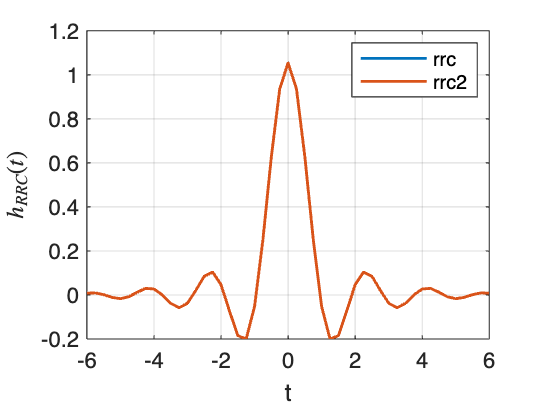

t=(-6:1/sps:6)';
alpha=0.2;
T=1/Rs;
hrrc=rrc(t,alpha,T);
hrrc2=rrc2(t,alpha,T);
clf;
figure;
plot(t,hrrc,'LineWidth',1.3)
hold on
plot(t,hrrc2,'LineWidth',1.3)
hold off
grid on
xlabel('t')
ylabel('$h_{RRC}(t)$', 'Interpreter', 'latex')
legend('rrc','rrc2')

#### Effect of RRC Filter Roll-off Factor $\alpha$ on BER

Roll-factor $\alpha$ of RRC filter measures the additional bandwidth that the filter occupies beyond the Nyquist bandwidth in frequency domain. The Nyquist bandwidth is defined as $B_{\mathrm{Nyquist}} =\frac{1}{2T}$, where $T=\frac{1}{R_s }$.

Although an RRC filter with a higher roll-off factor $\alpha$ requires more bandwidth, it has a smoother impulse response in the time domain (Figure 1), which reduces overlap between adjacent symbols and better prevents intersymbol interference (ISI). In contrast, an RRC filter with a lower roll-off factor $\alpha$ uses less bandwidth but has a sharper, more jittery impulse response, leading to higher BER due to increased ISI. 

Thus, there's a trade-off between bandwidth and BER: 

higher roll-off factors improve BER at the cost of additional bandwidth, while lower roll-off factors conserve bandwidth but can result in higher BER due to greater ISI.

From the plot 'Impact of RRC Roll-off Factor on BER,' we observe that a roll-off factor of α = 0 results in a higher BER compared to α = 1. The result is consistent with the expectation based on our analysis.

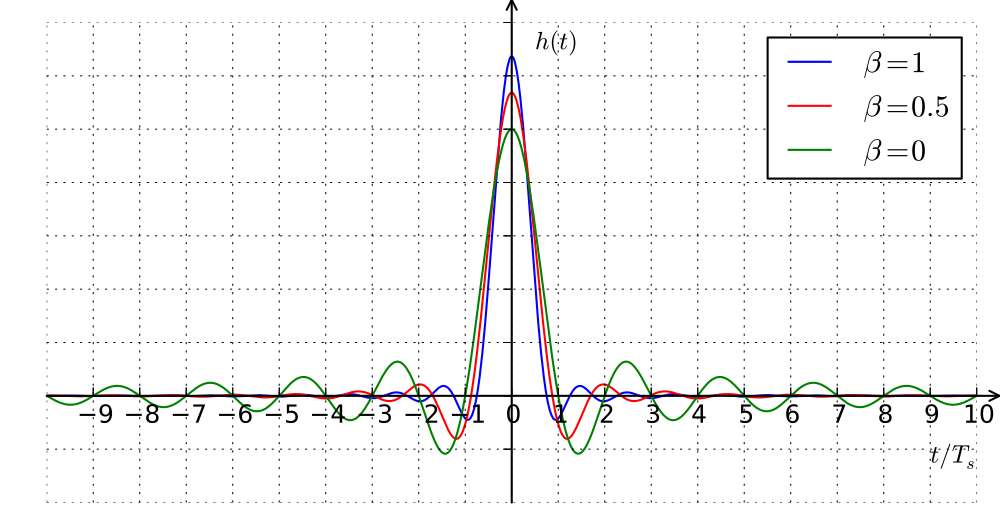

Figure 1. Impulse response of RRC filter in time domain (*Wikipedia: Root-raised-cosine filter, *[*https://en.wikipedia.org/wiki/Root-raised-cosine_filter*](https://en.wikipedia.org/wiki/Root-raised-cosine_filter)* )*

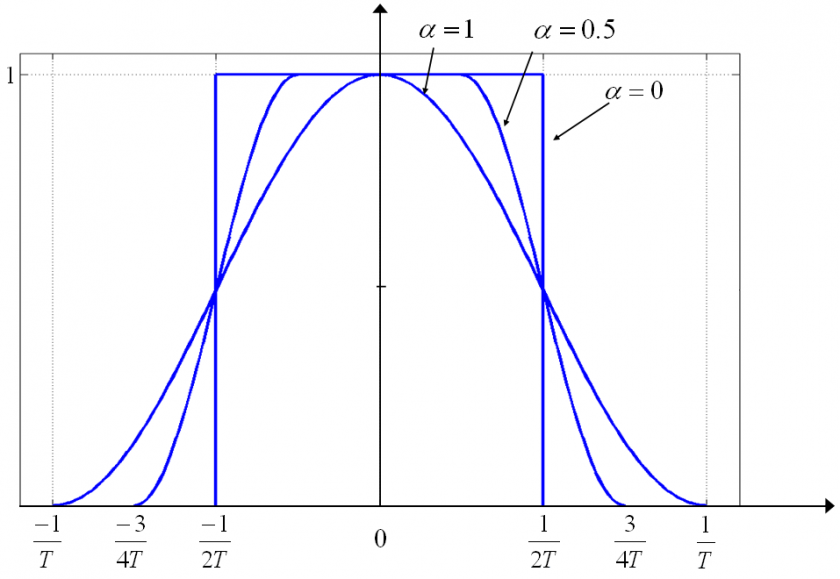

Figure 2. Impulse response of RRC filter in frequency domain *(Navipedia: Root-raised-cosine signals, *[*https://gssc.esa.int/navipedia/index.php/Square-Root_Raised_Cosine_Signals_%28SRRC%29*](https://gssc.esa.int/navipedia/index.php/Square-Root_Raised_Cosine_Signals_%28SRRC%29)* )*

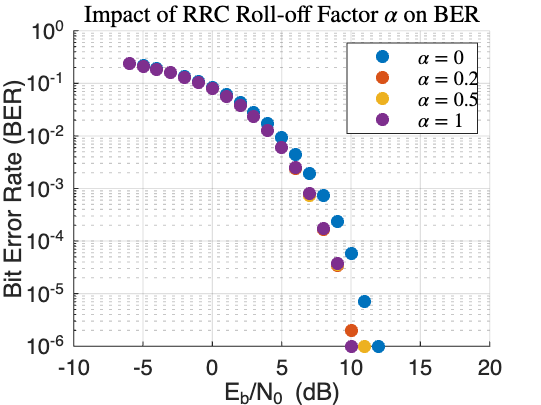

alpha=[0 0.2 0.5 1];
for k=1:length(alpha)
    hrrc = rrc2((-6:1/sps:6)',alpha(k),1); 
    
    % Tx
    bitvec = randi([0,1],[Nbits,1]); % Generate random bits
    symvec = complex(2*bitvec(1:2:end)-1,2*bitvec(2:2:end)-1)/sqrt(2);
    txvec = conv(upsample(symvec,sps),hrrc,'same');
    
    BER=zeros(1,length(EsN0dB));
    for i=1:length(EsN0dB)
        
        sig2 = (N0(i)/2)*Fs;
        noisevec = sqrt(sig2)*complex(randn(size(txvec)),randn(size(txvec)));
        % Rx
        rxvec = txvec + noisevec; % length=(2e6x1)
        
        matched_filter=conv(rxvec,hrrc,'same');            % y(t)=rxvex*hrrc
        matched_filter_sample=matched_filter(1:sps:end);   % downsample y(t)
    
        % Demodulation
        [syms,decoded_bits]=qpskdetect(matched_filter_sample);
        BER(i)=sum(xor(bitvec,decoded_bits))/Nbits;
    end
    scatter(EbN0dB,BER,'filled')
    hold on
end

set(gca,'yscale','log')
grid on
hold off
xlabel('E_b/N_0 (dB)', 'Interpreter', 'tex');
ylabel('Bit Error Rate (BER)');
title('Impact of RRC Roll-off Factor $\alpha$ on BER', 'Interpreter', 'latex');
legend({'$\alpha=0$', '$\alpha=0.2$', '$\alpha=0.5$','$\alpha=1$'}, 'Interpreter', 'latex')